clear all, close all, clc

## Prob-3.1a

Given

P_s1 = 0.2;         % probability of pump failure
P_s2 = 0.02;        % ..of power failure
P_s3 = 0.02;        % ..of pipe failure

P_s_s1 = 0.7;       % probability of loop failure, given pump failed
P_s_s2 = 1;         % ..., given power failed
P_s_s3 = 0.3;       % ..., given pipe failed

Now, we know from Bayes' theorem, we know-


$$P{\left(H\right)}=\sum_1^N P\left(E_i \;H\right)=\sum_1^N \left.P\left(H\right|E_i \right)\;P\left(E_i \right)$$


So, we have, the total probab' of loop failure-

P_s = P_s1 *P_s_s1 + P_s2 *P_s_s2 + P_s3 *P_s_s3 

P_s = 0.1660

Then, we find the following-

P_s1_s = P_s1 *P_s_s1 /P_s      % probab' of pump failure, given loop failed

P_s1_s = 0.8434

P_s2_s = P_s2 *P_s_s2 /P_s      % ...power failure,....

P_s2_s = 0.1205

P_s3_s = P_s3 *P_s_s3 /P_s      % ...pipe failure,....

P_s3_s = 0.0361

(Ans)

## Prob-3.1b

When all system works independly, we get the following

P_ss1 = P_s1 *P_s_s1        % probab' of loop and pump failure

P_ss1 = 0.1400

P_ss2 = P_s2 *P_s_s2        % ... loop and power failure

P_ss2 = 0.0200

P_ss3 = P_s3 *P_s_s3        % ... loop and pipe failure

P_ss3 = 0.0060

So, conjointly, probablity of failure for this condition

P_s = P_ss1 + P_ss2 + P_ss3

P_s = 0.1660

(Ans)

## Prob-3.1c

Now, this is a classic condition with subsystem with standby. This looks like-

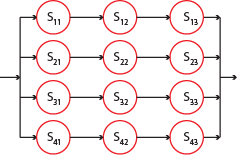  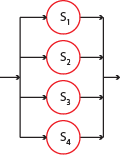

Now, we have-

Pw_s = 1 - P_s      % probab' of system working

Pw_s = 0.8340

Now, from binomial probability, let's find the probab' of 3 loop working outta 4-

    n = 4;      % no. of installed loops
    m = 3;      % no. of working loops
Pw_3_4 = nchoosek(n,m) *Pw_s^m *(1 - Pw_s)^(n-m)

Pw_3_4 = 0.3852

And then, 4 out of 4 would be-

    n = 4;      % no. of installed loops
    m = 4;      % no. of working loops
Pw_4_4 = nchoosek(n,m) *Pw_s^m *(1 - Pw_s)^(n-m)

Pw_4_4 = 0.4838

So, the probablity of at-least 3 loop working-

Pw_3l = Pw_3_4 + Pw_4_4

Pw_3l = 0.8690

(Ans)

## Prob-3.2a

Given,

lm1 = 1e-6;         % hazard rate, main pump; h^-1
lm2 = 1e-5;         % h. rate, b-up pump
lm2s = 1e-7;        % h. rate, b-up pump, @ standby

Now, for a system with backup pump- which might fail when it is idle, it is-


$$R_{sy} {\left(t\right)}=\exp \left(-\lambda_1 t\right)+\frac{R_{sw} \lambda_1 }{\lambda_1 +\lambda_2^* -\lambda_2 }{\left[\exp {\left(-\lambda_2 t\right)}-\exp {\left(-\left(\lambda_1 +\lambda_2^* \right)t\right)}\ \right]}$$


t = 2000;               % system runtime; h
R1 = exp(-lm1*t);       % reliability of system w/o b.up
R_sw = 1;               % reliability of switch, assumed
    C1 = R_sw*lm1 /(lm1 + lm2s - lm2);      % defining a const.
R2b = C1 *( exp(-lm2*t) - exp(-(lm1 + lm2s)*t) )

R2b = 0.0020

                        % reliability, added by backup component

So, we get-

R_syb = R1 + R2b         % reliability of system with standby

R_syb = 1.0000

 Which almost tend to perfection

    (Ans)

## Prob-3.2b

Now, let's find it for a system without backup pump

We know, $R=e^{-\lambda t\;}$, and-

t = 2000;               % system runtime; h
R_sy = exp(-lm1*t)      % reliability of system, w/o standby

R_sy = 0.9980

    (Ans)

## Prob-3.3

Given,

P1 = 100;           % power output of generator 1; KW
P2 = 50;            % ...each of gen. 2; KW
P3 = 35;            % KW

We know, power and resistance relationship are-

$P=i^2 R_s$     Here, $R_s =$ effective resistance of system

So, for attaining different loads, these generators have to be assembled in terms of their resitance

### a) Peak Load, 100 KW

Arrangement, i.t.o, electrical resistance of generators-

Here, in each case, the total effective resistance (so, power) surpasses the resistance required for delivering needed load

A_p1 = P1                   % power, KW

A_p1 = 100

A_p2 = P2 + P2

A_p2 = 100

A_p3 = P3 + P3 + P3

A_p3 = 105

Reliability Block Diagram 

Now, let's evaluate the reliabilities for each-

syms t L
lm = L;                 % hazard rate; h^-1
R = exp(-lm*t);         % reliability of each component
R_p1 = R                % reliability for arrangement 1

$$R\_p1 = {\mathrm{e}}^{-L\,t}$$

R_p2 = R*R              % ...of 2

$$R\_p2 = {\mathrm{e}}^{-2\,L\,t}$$

R_p3 = R*R*R

$$R\_p3 = {\mathrm{e}}^{-3\,L\,t}$$

Now, let's plot them

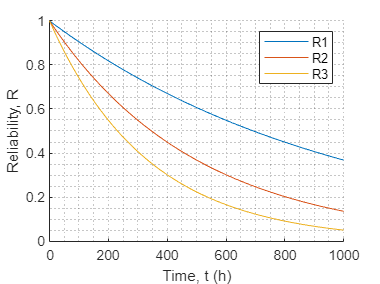

L = 1e-3;                       % assumed; h^-1
t = linspace(0,1e3, 1001);      % hours
R_p1 = eval(R_p1);              % evaluating the R's for peak load
R_p2 = eval(R_p2);
R_p3 = eval(R_p3);

figure()
grid minor, hold on
plot(t, R_p1, 'DisplayName', 'R1')
plot(t, R_p2, 'DisplayName', 'R2')
plot(t, R_p3, 'DisplayName', 'R3')
hold off

legend
xlabel('Time, t (h)')
ylabel('Reliability, R')

### b) Average Load, 70 KW

Arranngement, i.t.o resistance

A_v1 = P1               % power, KW

A_v1 = 100

A_v2 = P2 + P2

A_v2 = 100

A_v3 = P3 + P3          % with 1 P3 standby

A_v3 = 70

So, reliability block diagram

Now, let's find the reliability-

syms t L
lm = L;                 % hazard rate; h^-1
R = exp(-lm*t);         % reliability of each component
R_v1 = R                % reliability for arrangement 1

$$R\_v1 = {\mathrm{e}}^{-L\,t}$$

R_v2 = R*R              % ...of 2

$$R\_v2 = {\mathrm{e}}^{-2\,L\,t}$$

Let's use this equation for arrangement 3


$$R_{M\left|N\right.} {\left(t\right)}=\sum_{n,M}^N {\left(\begin{array}{c}
N\\
n
\end{array}\right)}{{\left[R{\left(t\right)}\right]}}^n {{\left(1-R{\left(t\right)}\right)}}^{N-n}$$
 

    N = 2;              % total components in redundant system
    C1 = nchoosek(2,1); % combinations
    C2 = nchoosek(2,2);
R_v3s = C1*R^N *(1-R)^(N-1) + C2*R^N *(1-R)^(N-2)       % reliability of subsystem with redundancy

$$R\_v3s = {\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

R_v3 = R * R_v3s

$$R\_v3 = {\mathrm{e}}^{-L\,t}\,\left({\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)\right)$$

Now, let's plot them-

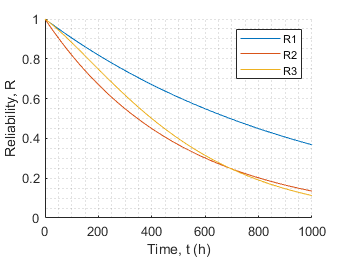

L = 1e-3;                       % assumed; h^-1
t = linspace(0,1e3, 1001);      % hours
R_v1 = eval(R_v1);              % evaluating the R's for avg. load
R_v2 = eval(R_v2);
R_v3 = eval(R_v3);

figure()
grid minor, hold on
plot(t, R_v1, 'DisplayName', 'R1')
plot(t, R_v2, 'DisplayName', 'R2')
plot(t, R_v3, 'DisplayName', 'R3')
hold off

legend
xlabel('Time, t (h)')
ylabel('Reliability, R')

### c) Base Load, 50 KW

Arrangement, i.t.o resistance-

A_b1 = P1

A_b1 = 100

A_b2 = P2                           % with 1 P2 standby

A_b2 = 50

A_b3 = P3 + P3                      % KW

A_b3 = 70

So, reliability block diagram-

Let's calculate the reliability-

syms t L
lm = L;                 % hazard rate; h^-1
R = exp(-lm*t);         % reliability of each component
R_b1 = R                % reliability for arrangement 1

$$R\_b1 = {\mathrm{e}}^{-L\,t}$$

Now, for 2nd arrangement-


$$R_{M\left|N\right.} {\left(t\right)}=\sum_{n,M}^N {\left(\begin{array}{c}
N\\
n
\end{array}\right)}{{\left[R{\left(t\right)}\right]}}^n {{\left(1-R{\left(t\right)}\right)}}^{N-n}$$
 

    N = 2;              % total components in redundant system
    C1 = nchoosek(2,1); % combinations
    C2 = nchoosek(2,2);
R_b2s = C1*R^N *(1-R)^(N-1) + C2*R^N *(1-R)^(N-2)       % reliability of subsystem with redundancy

$$R\_b2s = {\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

R_b2 = R_b2s

$$R\_b2 = {\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

And, for 3rd arrangement-

    N = 2;              % total components in redundant system
    C1 = nchoosek(2,1); % combinations
    C2 = nchoosek(2,2);
R_b3s = C1*R^N *(1-R)^(N-1) + C2*R^N *(1-R)^(N-2)       % reliability of subsystem with redundancy

$$R\_b3s = {\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)$$

R_b3 = R * R_b2s

$$R\_b3 = {\mathrm{e}}^{-L\,t}\,\left({\mathrm{e}}^{-2\,L\,t}-2\,{\mathrm{e}}^{-2\,L\,t}\,\left({\mathrm{e}}^{-L\,t}-1\right)\right)$$

Let's plot them-

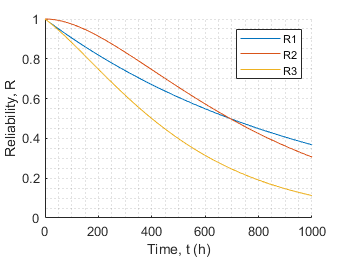

L = 1e-3;                       % assumed; h^-1
t = linspace(0,1e3, 1001);      % hours
R_b1 = eval(R_b1);              % evaluating the R's for base load
R_b2 = eval(R_b2);
R_b3 = eval(R_b3);

figure()
grid minor, hold on
plot(t, R_b1, 'DisplayName', 'R1')
plot(t, R_b2, 'DisplayName', 'R2')
plot(t, R_b3, 'DisplayName', 'R3')
hold off

legend
xlabel('Time, t (h)')
ylabel('Reliability, R')